# PL1- Examen Matlab 21-22 (Abidán Brito)

#### EJERCICIO 1.1

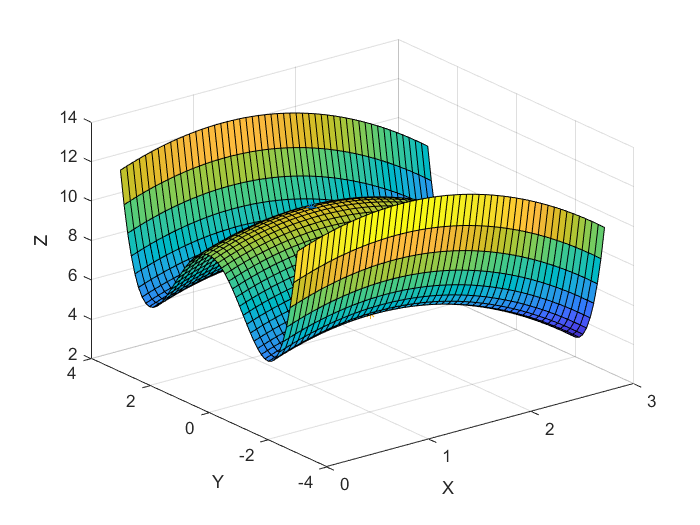

% Vectores de coeficientes equiespaciados de los lados, dominio (x, y)
x = linspace(0, 3, 50);
y = linspace(-3, 3, 50);

% Construcción de la malla reglada (matrices de coordenadas X e Y)
[X, Y] = meshgrid(x, y);

% Cómputo de la matriz de coordenadas Z
Z = 2 * X - X.^2 - 2 * Y.^2 + (1/4 .* Y.^4) + 10;

% Representación en el espacio euclídeo
figure
surf(X, Y, Z)
xlabel('X'), ylabel('Y'), zlabel('Z')

% (1, 0, z1)
% z1 = 11
hold on, plot3(1, 0, 11, '*')

% (1, 2, z2)
% z2 = 7
plot3(1, 2, 7, '*')

% (1, -2, z3)
% z3 = 7
plot3(1, -2, 7, '*')

**Contestación a la pregunta y razonamiento: **no, es un máximo relativo, porque al considerar todo el plano se observa puntos de altitud mayor, es decir, no es un máximo absoluto.

**EJERCICIO 1.2**

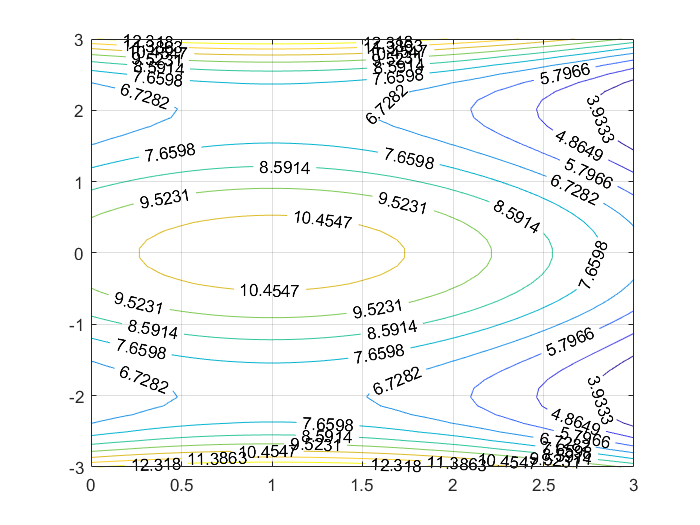

% Curvas de nivel (10 curvas)
figure
[C, h] = contour(X, Y, Z, 10);
clabel(C, h), grid

**EJERCICIO 1.3**

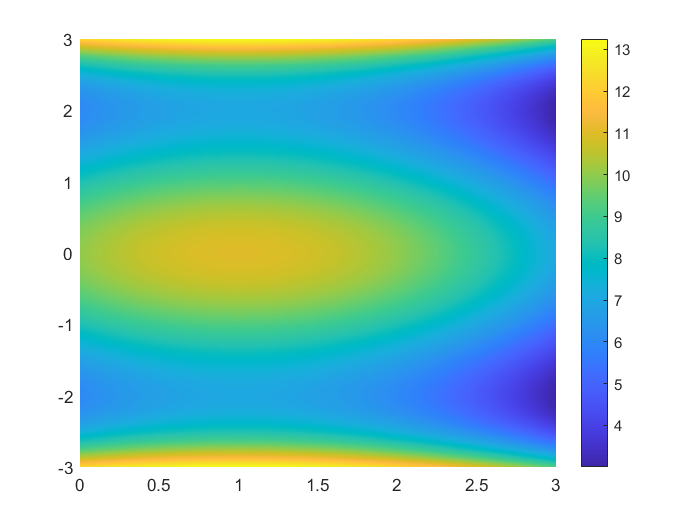

% Mapa de color
figure
pcolor(X, Y, Z), shading interp
colorbar

**EJERCICIO 2**

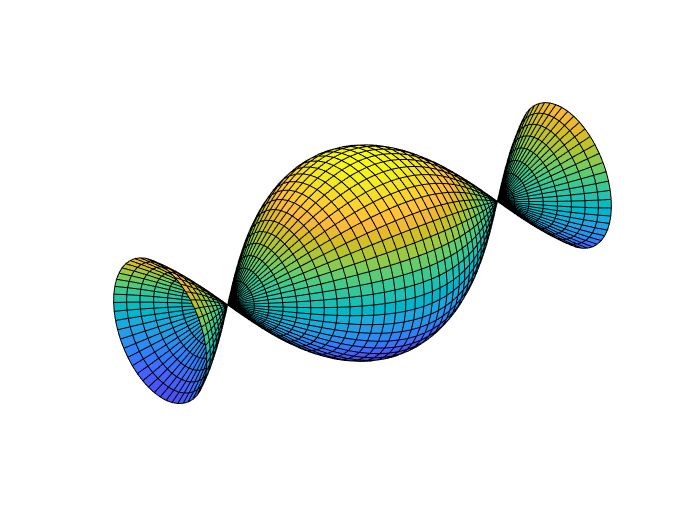

% Vectores de coeficientes equiespaciados de los lados, dominio (u, v)
u = linspace(-3 * pi / 4, 3 * pi / 4, 50);
v = linspace(0, 2 * pi, 50);

% Generamos la malla reglada 
[U, V] = meshgrid(u, v);

% Matrices de coordenadas cartesianas
X = U;
Y = cos(U) .* sin(V);
Z = cos(U) .* cos(V);

% Representación de la superficie en el espacio euclídeo
figure
surf(X, Y, Z);

% Desactivamos los ejes
axis equal, axis off

**EJERCICIO 3.1**

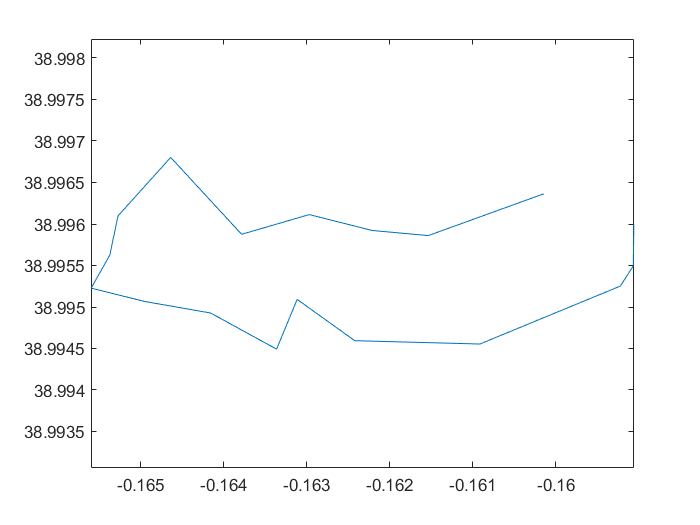

% Vectores con las coordenadas de los puntos donde se tienen medidas
y = [38.99636614,38.99586259,38.99592314,38.99611121,38.99587472,38.9968032,38.99609917,38.99562512,38.99522703,38.99506752,38.9949254,38.99449128,38.99509093,38.99459392,38.99455198,38.99524904,38.99549311,38.99599604];
x = [-0.16014483,-0.16153612,-0.16221429,-0.16297008,-0.16378434,-0.16463896,-0.1652732,-0.16537253,-0.16559699,-0.16495243,-0.16415897,-0.1633635,-0.16311573,-0.16242139,-0.16091453,-0.15922224,-0.15906601,-0.15905958];

% Niveles de NO2 en µg/m3, observados en (x, y)
Lno2 = [46,149,197,278,250,215,192,235,268,268,288,278,248,217,260,380,425,290];

plot(x, y), axis equal

**Contestación a las preguntas:  **se comprueba que sí constituyen una malla rectangular equiespaciada (en cada eje), aunque la distancia entre los valores de las x es el doble de los de la y. Es importante que los puntos conforme una malla rectangular para poder aplicar interpolación.

**EJERCICIO 3.2 **

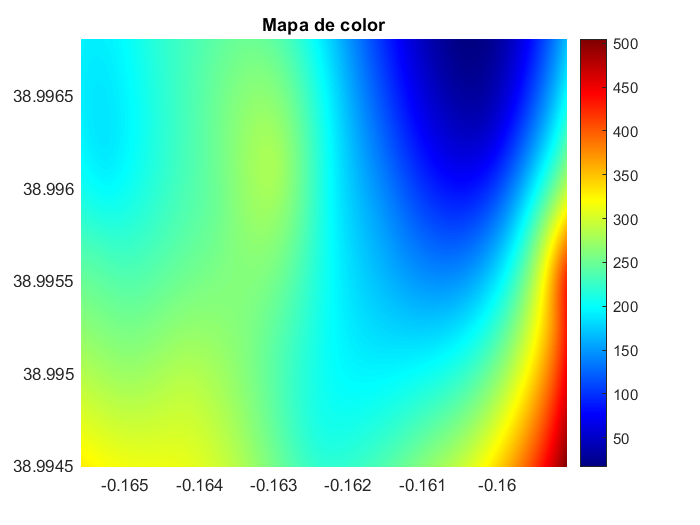

% Generamos una nueva malla rectangular 
% NOTA: los valores iniciales han de estar contenidos.
x1 = linspace(min(x), max(x), 200);
y1 = linspace(min(y), max(y), 50);

[X1, Y1] = meshgrid(x1, y1);

% NOTA: v4 es un tipo de interpolación propia de Matlab.
LNO2 = griddata(x, y, Lno2, X1, Y1, 'v4');

% Gráfico de densidad de color
pcolor(X1, Y1, LNO2), shading interp
colorbar, colormap jet
title('Mapa de color')

**EJERCICIO 3.3**

En la EPSG no se cumple la normativa. Aunque se encuentra en el límite, se comprueba que en algunas zonas del rectángulo de la figura del enunciado, el valor llega hasta los 250 µg/m3.

**EJERCICIO 4.1**

% Definición de la función simbólica y(t)
syms p(t)

% Definición de la primera derivada 
Dp = diff(p);

% Definición de la ecuación diferencial
eqn = Dp == (15 / 32) * p * (1 - (p / 1500));

% Definición de la condición inicial
cond1 = p(0) == 100 ;   
cond2 = p(0) == 2500;  
p1 = dsolve(eqn, cond1)

$$p1 = \frac{1500}{{\mathrm{e}}^{\log\left(14\right)-\frac{15\,t}{32}}+1}$$

p2 = dsolve(eqn, cond2)

$$p2 = -\frac{1500}{{\mathrm{e}}^{\log\left(\frac{2}{5}\right)-\frac{15\,t}{32}}-1}$$

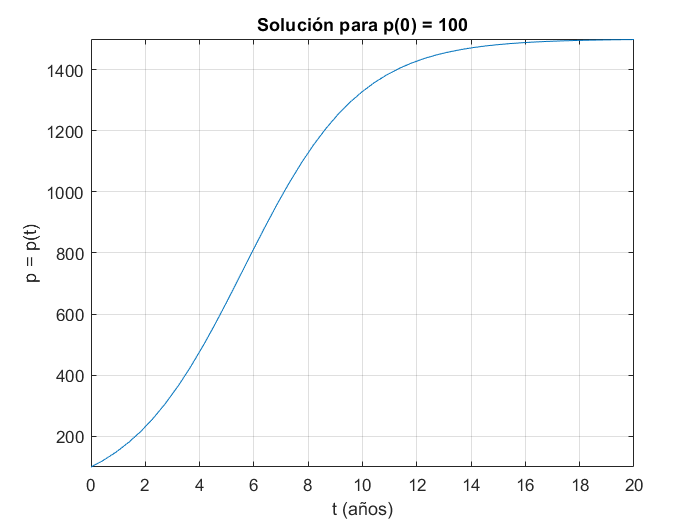


% Representación de la función durante los primeros 20 años con población
% de 100
fplot(p1, [0, 20]), grid
xlabel('t (años)'), ylabel('p = p(t)'), title("Solución para p(0) = 100")

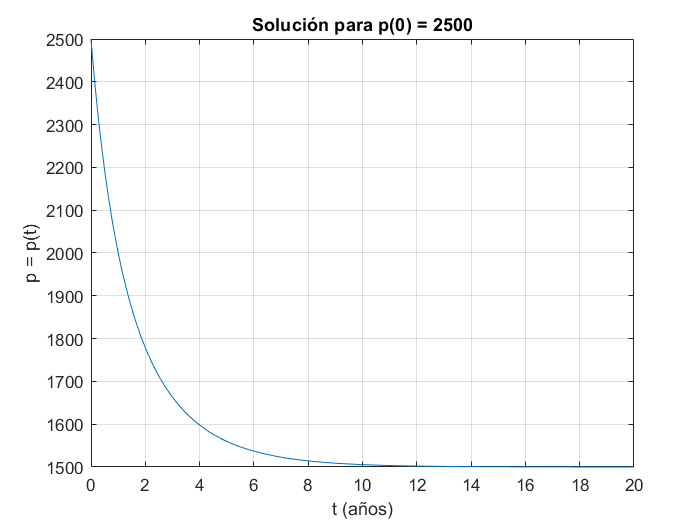


% Representación de la función durante los primeros 20 años con población
% de 2500
fplot(p2, [0, 20]), grid
xlabel('t (años)'), ylabel('p = p(t)'), title("Solución para p(0) = 2500")

**Razonamiento:** para una población inicial de 100 animales, se ve un claro aumento en la población durante esos 20 años, mientras que para 2500 animales se observa el caso contrario, una brusca disminución en la población. Esto probablemente se debe a que la población de depredadores está ligada de manera proporcional a la de estos animales. Así pues, cuando la población inicial es escasa, también lo será la de los depredadores, y por ende su reproducción aumenta. Para una población abundante ocurre lo opuesto.

**EJERCICIO 4.2**

C1 = 30, C2 = 43, C3 = 43.75;

C1 = 30

C2 = 43


eqn1 = Dp == (15 / 32) * p * (1 - (p / 1500)) - C1;
eqn2 = Dp == (15 / 32) * p * (1 - (p / 1500)) - C2;
eqn3 = Dp == (15 / 32) * p * (1 - (p / 1500)) - C3;

% Definición de la condición inicial
p1 = dsolve(eqn1, cond1)

$$p1 = 10\,\sqrt{4665}\,\tanh\left(\frac{\sqrt{4665}\,\left(933\,t-64\,\sqrt{4665}\,\mathrm{atanh}\left(\frac{13\,\sqrt{4665}}{933}\right)\right)}{298560}\right)+750$$

p2 = dsolve(eqn2, cond1)

$$p2 = 10\,\sqrt{4249}\,\tanh\left(\frac{\sqrt{4249}\,\left(4249\,t-320\,\sqrt{4249}\,\mathrm{atanh}\left(\frac{65\,\sqrt{4249}}{4249}\right)\right)}{1359680}\right)+750$$

p3 = dsolve(eqn3, cond1)

$$p3 = 100$$

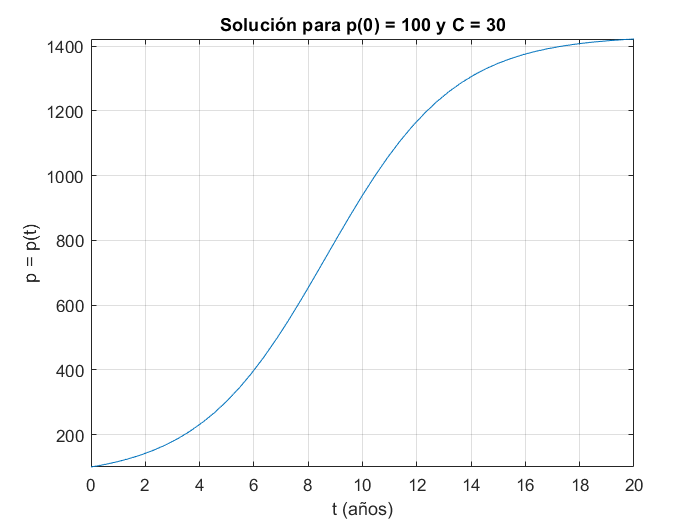


fplot(p1, [0, 20]), grid
xlabel('t (años)'), ylabel('p = p(t)'), title("Solución para p(0) = 100 y C = 30")

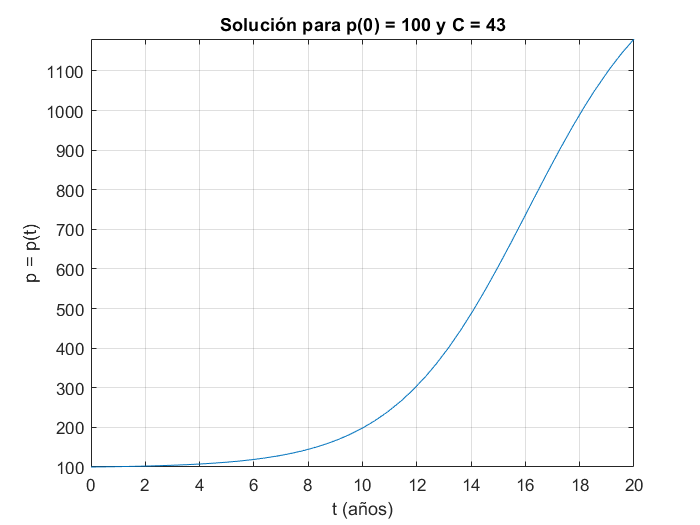


fplot(p2, [0, 20]), grid
xlabel('t (años)'), ylabel('p = p(t)'), title("Solución para p(0) = 100 y C = 43")

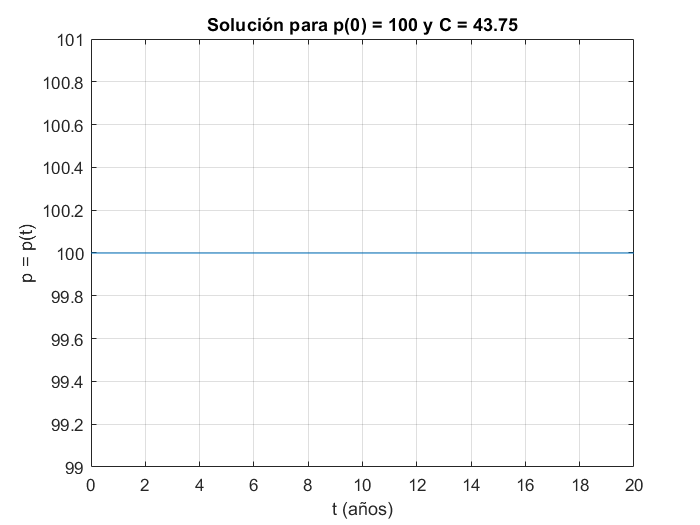


fplot(p3, [0, 20]), grid
xlabel('t (años)'), ylabel('p = p(t)'), title("Solución para p(0) = 100 y C = 43.75")

**Razonamiento:** si observamos las gráficas de las figuras adjuntas, vemos que al aumentar la cota de caza, se estabiliza este crecimiento y decrecimiento cíclico, llegando a estabilizarse en el caso de C = 43.75, es decir, se mantendría estable la población de animales.

**EJERCICIO 5 (Runge Kutta)**

clear

% Solución del sistema de ecuaciones diferenciales por RK4
F = @(t, y)[- 4*y(1)^3 + 4*y(1) - 4*y(2);
    - 4*y(2)^3 - 4*y(1) + 4*y(2)];

[T, Y] = ode45(F, [0, 1], [0.5, 10]);

% Punto final de la trayectoria
ultimo = length(Y);
Y(ultimo, :)

ans =    -1.4142    1.4142


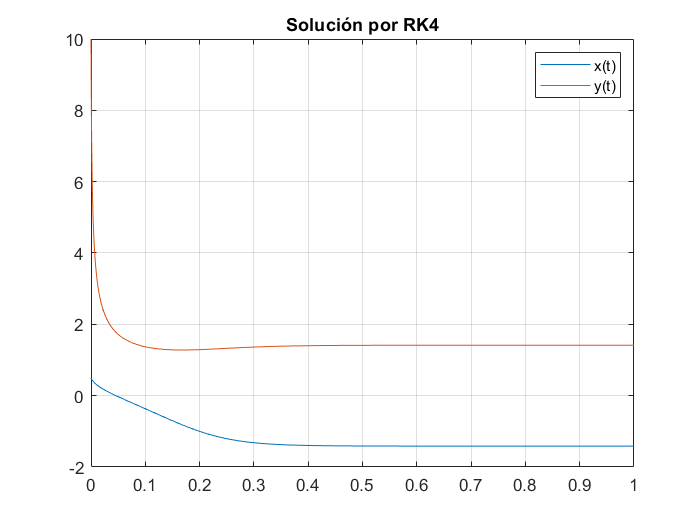


% Representación
plot(T, Y), grid
title('Solución por RK4'), legend('x(t)','y(t)')

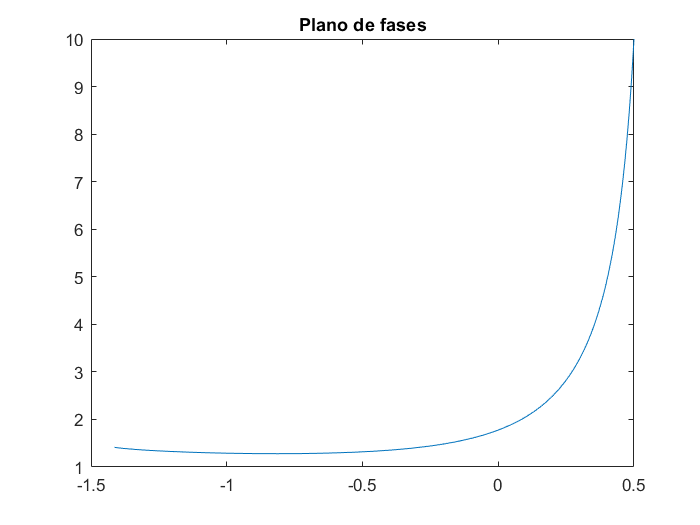


% Representación en el plano de fases
plot(Y(:,1) ,Y(:,2)), title('Plano de fases')